cd('G:\My Drive\Matlab_work\BC\SMIIL\SeniorSeminar\Data_Analysis\Data')
load PondData.mat
load Met.mat % Latitude 39°03'25",   Longitude 74°45'54" 
cd('G:\My Drive\Matlab_work\BC\SMIIL\SeniorSeminar\Data_Analysis') 
load HOBO.mat
load Gull.mat
run('GeneralSettings.m')

% Met variables in kms units

met.dn = datenum(met.DateTime);
met.airtemp_C = (5/9)*(met.AirTempF-32); % Celsius = (5/9)*(Fahrenheit-32); 
met.windspeed_ms = met.WindSpeed_mph*1609.34/3600; % mph --> m/s
met.Precip_cm = met.Precip_in/2.54; % inches to cm of rain
%Windspeed to time of pond measurements 
pond.windspeed_ms = interp1(met.dn,met.windspeed_ms,pond.dn);

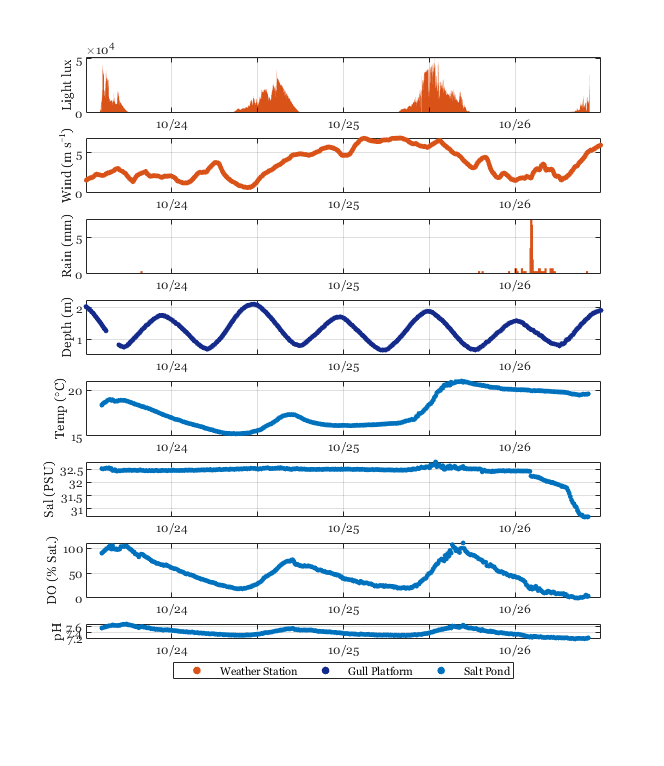


f = figure;
set(gca, 'FontName', 'Georgia');
f.Position = [0 0 1040 1200]; 

ax1 = subplot(8,1,1);
bar(hobo.dn,hobo.light_lux,'FaceColor',red,'BarWidth',1.2) % What are these units? 
ylabel('Light (lux)','FontName','Georgia')  
xlim([datenum(2021,10,23,12,00,00) datenum(2021,10,26,12,00,00)])
grid on
set(ax1,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax1 = subplot(8,1,2);
plot(met.dn,movmean(met.windspeed_ms,18),'o','Color',red,'MarkerSize',3,'MarkerFaceColor',red)
ylabel('Wind (m s^-^1)','FontName','Georgia')  
xlim([datenum(2021,10,23,12,00,00) datenum(2021,10,26,12,00,00)])
grid on
set(ax1,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax1 = subplot(8,1,3);
bar(met.dn,met.Precip_cm*100,'BarWidth',3,'FaceColor',red)
ylabel('Rain (mm)','FontName','Georgia')  
xlim([datenum(2021,10,23,12,00,00) datenum(2021,10,26,12,00,00)])
grid on
set(ax1,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax1 = subplot(8,1,4);
plot(gull.dn,gull.Depth1_m,'o','Color',navy,'MarkerSize',3,'MarkerFaceColor',navy)
ylabel('Depth (m)','FontName','Georgia')  
xlim([datenum(2021,10,23,12,00,00) datenum(2021,10,26,12,00,00)])
ylim([0.5 2.25])
grid on
set(ax1,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax2 = subplot(8,1,5);
plot(pond.dn,pond.temp,'o','MarkerSize',3,'MarkerFaceColor',blue)
ylabel('Temp (\circC)','FontName','Georgia')   
xlim([datenum(2021,10,23,12,00,00) datenum(2021,10,26,12,00,00)])
grid on
set(ax2,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax3 = subplot(8,1,6); 
plot(pond.dn,pond.sal,'o','MarkerSize',3,'MarkerFaceColor',blue) 
ylabel('Sal (PSU)','FontName','Georgia') 
xlim([datenum(2021,10,23,12,00,00) datenum(2021,10,26,12,00,00)])
grid on
set(ax3,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax4 = subplot(8,1,7);
plot(pond.dn,pond.DOper,'o','MarkerSize',3,'MarkerFaceColor',blue)
ylabel('DO (% Sat.)','FontName','Georgia') %change to percent
xlim([datenum(2021,10,23,12,00,00) datenum(2021,10,26,12,00,00)])
grid on
set(ax4,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});

ax5 = subplot(8,1,8);
plot(datenum(2021,10,22,12,00,00),7.6,'o','MarkerSize',5,'Color',red,'MarkerFaceColor',red) 
hold on
plot(datenum(2021,10,22,12,00,00),7.5,'o','MarkerSize',5,'Color',navy,'MarkerFaceColor',navy) 
plot(datenum(2021,10,22,12,00,00),7.5,'o','Color',blue,'MarkerSize',5,'MarkerFaceColor',blue) 
plot(pond.dn,pond.pH,'o','Color',blue,'MarkerSize',3,'MarkerFaceColor',blue) 
ylabel('pH','FontName','Georgia') 
xlim([datenum(2021,10,23,12,00,00) datenum(2021,10,26,12,00,00)])
grid on
set(ax5,'FontName','Georgia','XTick',...
    [738452 738452.5 738453 738453.5 738454 738454.5 738455 738455.5 738456],...
    'XTickLabel',{'10/23','','10/24','','10/25','','10/26','','10/27'});
legend('Weather Station','Gull Platform','Salt Pond','Location','southoutside','Orientation',"horizontal")